ts=0.6;
fs=1/ts

fs = 1.6667


N=512;
k=0:N-1;
td=k*ts;
p0=70;
f0=fs/6;%cumpliendo el teorema de nyquist
w=2*pi*f0

w = 1.7453

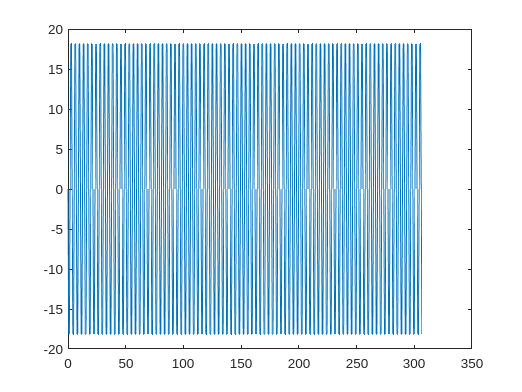

v0=12;
x_n=-(v0*w)*sin(w*td);
plot(td,x_n)

v=[x_n ;zeros(1,N)]'

v =          0         0
  -18.1380         0
  -18.1380         0
   -0.0000         0
   18.1380         0
   18.1380         0
    0.0000         0
  -18.1380         0
  -18.1380         0
   -0.0000         0


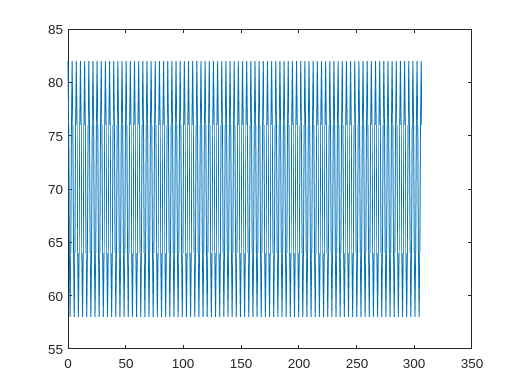

A=v0;
p_n=p0+A*cos(w*td);
figure
plot(td,p_n)

b=30%cm distancia entre robots o markers de la base del triangulo isosceles

b = 30

a=sqrt(p_n.^2+ (b/2)^2);%lados iguales del triangulo isosceles
h=p_n;
alpha123=asin(h./a);
alpha312=asin(b/2./a);
alpha231=pi-alpha123-alpha312;


for i=2:N
    Dalpha123=(alpha123(i)-alpha123(i-1))/ts;
    Dalpha312=(alpha312(i)-alpha312(i-1))/ts;
    Dalpha231=(alpha231(i)-alpha231(i-1))/ts;
    m2_21=M2_21(alpha123(i),alpha312(i),alpha231(i),Dalpha231,Dalpha123,Dalpha312);
    m2_12=M2_12(alpha123(i),alpha312(i),Dalpha123,Dalpha312);
    m2_123=M2_123(alpha123(i),alpha231(i),Dalpha123,Dalpha231,m2_12,m2_21);
    M2_123_inv=inv(m2_123);
    pn=M2_123_inv*[sin(alpha123(i))*rot(alpha312(i))'*v(i,[1 2])' - sin(alpha231(i))*v(i,[1 2])';sin(alpha231(i))*rot(alpha231(i))'*v(i,[1 2])']

end

pn =   766.0527
 -180.4709
  148.3331
   29.2763


pn =   299.6880
  -86.2674
   68.3862
   16.0280


pn = 	1.0e+-12 *

    0.3016
   -0.0975
    0.0755
    0.0195


pn =   463.5823
 -133.4456
  105.7855
   24.7935


pn =   301.9835
  -71.1429
   58.4740
   11.5409


pn = 	1.0e+-11 *

    0.1005
   -0.0217
    0.0181
    0.0033


pn =   766.0527
 -180.4709
  148.3331
   29.2763


pn =   299.6880
  -86.2674
   68.3862
   16.0280


pn = 	1.0e+-12 *

    0.1956
   -0.0632
    0.0490
    0.0127


pn =   463.5823
 -133.4456
  105.7855
   24.7935


pn =   301.9835
  -71.1429
   58.4740
   11.5409


pn = 	1.0e+-11 *

    0.2010
   -0.0434
    0.0362
    0.0066


pn =   766.0527
 -180.4709
  148.3331
   29.2763


pn =   299.6880
  -86.2674
   68.3862
   16.0280


pn = 	1.0e+-12 *

    0.3259
   -0.1054
    0.0816
    0.0211


pn =   463.5823
 -133.4456
  105.7855
   24.7935


pn =   301.9835
  -71.1429
   58.4740
   11.5409


pn = 	1.0e+-12 *

    0.6517
   -0.1407
    0.1173
    0.0215


pn =   766.0527
 -180.4709
  148.3331
   29.2763


pn =   299.6880
  -86.2674
   68.3862
   16.0280


pn = 	1.0e+-12 *

    0.4563
   -0.1476
    0.1143
    0.0295


pn =   463.5823
 -133.4456
  105.7855
   24.7935


pn =   301.9835
  -71.1429
   58.4740
   11.5409


pn = 	1.0e+-11 *

    0.4020
   -0.0868
    0.0723
    0.0132


pn =   766.0527
 -180.4709
  148.3331
   29.2763


pn =   299.6880
  -86.2674
   68.3862
   16.0280


pn = 	1.0e+-12 *

    0.5867
   -0.1897
    0.1469
    0.0380


pn =   463.5823
 -133.4456
  105.7855
   24.7935


pn =   301.9835
  -71.1429
   58.4740
   11.5409


pn = 	1.0e+-11 *

    0.1086
   -0.0234
    0.0195
    0.0036


pn =   766.0527
 -180.4709
  148.3331
   29.2763


pn =   299.6880
  -86.2674
   68.3862
   16.0280


pn = 	1.0e+-11 *

   -0.1174
    0.0380
   -0.0294
   -0.0076


pn =   463.5823
 -133.4456
  105.7855
   24.7935


pn =   301.9835
  -71.1429
   58.4740
   11.5409


pn = 	1.0e+-11 *

    0.1303
   -0.0281
    0.0235
    0.0043


pn =   766.0527
 -180.4709
  148.3331
   29.2763


pn =   299.6880
  -86.2674
   68.3862
   16.0280


pn = 	1.0e+-11 *

    0.2739
   -0.0886
    0.0686
    0.0177


pn =   463.5823
 -133.4456
  105.7855
   24.7935


pn =   301.9835
  -71.1429
   58.4740
   11.5409


pn = 	1.0e+-11 *

    0.1521
   -0.0328
    0.0274
    0.0050


pn =   766.0527
 -180.4709
  148.3331
   29.2763


pn =   299.6880
  -86.2674
   68.3862
   16.0280


pn = 	1.0e+-12 *

   -0.9133
    0.2953
   -0.2287
   -0.0591


pn =   463.5823
 -133.4456
  105.7855
   24.7935


pn =   301.9835
  -71.1429
   58.4740
   11.5409


pn = 	1.0e+-11 *

    0.8040
   -0.1735
    0.1447
    0.0265


pn =   766.0527
 -180.4709
  148.3331
   29.2763


pn =   299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.2999
   -0.0970
    0.0751
    0.0194


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.1955
   -0.0422
    0.0352
    0.0064


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.3130
   -0.1012
    0.0784
    0.0203


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.2172
   -0.0469
    0.0391
    0.0072


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.7042
   -0.2277
    0.1763
    0.0456


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

   -0.3912
    0.0844
   -0.0704
   -0.0129


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.3390
   -0.1096
    0.0849
    0.0220


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.2607
   -0.0563
    0.0469
    0.0086


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-12 *

   -0.2614
    0.0845
   -0.0655
   -0.0169


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.9126
   -0.1970
    0.1642
    0.0300


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

   -0.3913
    0.1265
   -0.0980
   -0.0253


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.3041
   -0.0656
    0.0547
    0.0100


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.7564
   -0.2446
    0.1894
    0.0490


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

   -0.3043
    0.0657
   -0.0548
   -0.0100


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.3912
   -0.1265
    0.0979
    0.0253


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1608
   -0.0347
    0.0289
    0.0053


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-12 *

    0.2601
   -0.0841
    0.0651
    0.0168


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.9995
   -0.2157
    0.1798
    0.0329


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.4173
   -0.1349
    0.1045
    0.0270


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.3910
   -0.0844
    0.0704
    0.0129


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.8085
   -0.2615
    0.2024
    0.0524


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1043
   -0.0225
    0.0188
    0.0034


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

   -0.3131
    0.1012
   -0.0784
   -0.0203


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.4345
   -0.0938
    0.0782
    0.0143


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.8346
   -0.2699
    0.2090
    0.0540


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.2347
   -0.0507
    0.0422
    0.0077


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.4694
   -0.1518
    0.1175
    0.0304


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

   -0.7825
    0.1689
   -0.1408
   -0.0258


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.1042
   -0.0337
    0.0261
    0.0067


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1130
   -0.0244
    0.0203
    0.0037


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1252
   -0.0405
    0.0313
    0.0081


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.5214
   -0.1125
    0.0938
    0.0172


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

   -0.6261
    0.2025
   -0.1568
   -0.0405


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-12 *

   -0.8711
    0.1880
   -0.1567
   -0.0287


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.5216
   -0.1687
    0.1306
    0.0338


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1825
   -0.0394
    0.0328
    0.0060


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1669
   -0.0540
    0.0418
    0.0108


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

   -0.1304
    0.0281
   -0.0235
   -0.0043


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

   -0.2088
    0.0675
   -0.0523
   -0.0135


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.6082
   -0.1313
    0.1094
    0.0200


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.9389
   -0.3036
    0.2351
    0.0608


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.2521
   -0.0544
    0.0454
    0.0083


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.5737
   -0.1855
    0.1436
    0.0372


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

   -0.6087
    0.1314
   -0.1095
   -0.0200


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.2085
   -0.0674
    0.0522
    0.0135


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1304
   -0.0281
    0.0235
    0.0043


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1356
   -0.0439
    0.0340
    0.0088


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.3216
   -0.0694
    0.0579
    0.0106


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.9910
   -0.3205
    0.2481
    0.0642


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-12 *

    0.8667
   -0.1871
    0.1560
    0.0285


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.6259
   -0.2024
    0.1567
    0.0405


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1999
   -0.0431
    0.0360
    0.0066


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1774
   -0.0574
    0.0444
    0.0115


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1390
   -0.0300
    0.0250
    0.0046


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

   -0.1045
    0.0338
   -0.0262
   -0.0068


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.7820
   -0.1688
    0.1407
    0.0257


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

   -0.4697
    0.1519
   -0.1176
   -0.0304


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.2694
   -0.0582
    0.0485
    0.0089


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.6780
   -0.2193
    0.1698
    0.0439


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.2086
   -0.0450
    0.0375
    0.0069


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.3128
   -0.1012
    0.0783
    0.0203


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

   -0.1043
    0.0225
   -0.0188
   -0.0034


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1461
   -0.0472
    0.0366
    0.0095


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.8689
   -0.1876
    0.1564
    0.0286


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.2608
   -0.0843
    0.0653
    0.0169


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.2781
   -0.0600
    0.0500
    0.0092


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

   -0.7827
    0.2531
   -0.1960
   -0.0507


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.4693
   -0.1013
    0.0845
    0.0154


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.3650
   -0.1180
    0.0914
    0.0236


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1564
   -0.0338
    0.0281
    0.0051


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1513
   -0.0489
    0.0379
    0.0098


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

   -0.1565
    0.0338
   -0.0282
   -0.0052


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.2660
   -0.0860
    0.0666
    0.0172


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.3473
   -0.0750
    0.0625
    0.0114


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.7823
   -0.2530
    0.1959
    0.0507


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.2260
   -0.0488
    0.0407
    0.0074


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

   -0.1096
    0.0354
   -0.0274
   -0.0071


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.4172
   -0.0900
    0.0751
    0.0137


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-12 *

    0.5195
   -0.1680
    0.1301
    0.0336


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1043
   -0.0225
    0.0188
    0.0034


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1200
   -0.0388
    0.0300
    0.0078


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

   -0.2087
    0.0450
   -0.0375
   -0.0069


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.2347
   -0.0759
    0.0588
    0.0152


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

   -0.1742
    0.0376
   -0.0313
   -0.0057


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.3495
   -0.1130
    0.0875
    0.0226


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1738
   -0.0375
    0.0313
    0.0057


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

   -0.1409
    0.0456
   -0.0353
   -0.0091


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.3650
   -0.0788
    0.0657
    0.0120


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

   -0.2611
    0.0844
   -0.0654
   -0.0169


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.5563
   -0.1201
    0.1001
    0.0183


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.8866
   -0.2867
    0.2220
    0.0574


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

   -0.2608
    0.0563
   -0.0469
   -0.0086


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.2034
   -0.0658
    0.0509
    0.0132


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

   -0.6958
    0.1502
   -0.1252
   -0.0229


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.3182
   -0.1029
    0.0797
    0.0206


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1216
   -0.0263
    0.0219
    0.0040


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1304
   -0.0422
    0.0326
    0.0084


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.3129
   -0.0675
    0.0563
    0.0103


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

   -0.5741
    0.1857
   -0.1437
   -0.0372


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.5041
   -0.1088
    0.0907
    0.0166


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.5736
   -0.1855
    0.1436
    0.0371


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1912
   -0.0413
    0.0344
    0.0063


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1721
   -0.0557
    0.0431
    0.0111


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

   -0.1217
    0.0263
   -0.0219
   -0.0040


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.2869
   -0.0928
    0.0718
    0.0186


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.6949
   -0.1500
    0.1250
    0.0229


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.9909
   -0.3204
    0.2481
    0.0642


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.2607
   -0.0563
    0.0469
    0.0086


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

   -0.8871
    0.2869
   -0.2221
   -0.0574


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.4519
   -0.0975
    0.0813
    0.0149


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.2606
   -0.0843
    0.0652
    0.0169


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.6432
   -0.1388
    0.1157
    0.0212


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1408
   -0.0455
    0.0353
    0.0091


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.3303
   -0.0713
    0.0594
    0.0109


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.2556
   -0.0827
    0.0640
    0.0166


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

    0.1733
   -0.0374
    0.0312
    0.0057


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.3704
   -0.1198
    0.0927
    0.0240


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.2086
   -0.0450
    0.0375
    0.0069


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1826
   -0.0590
    0.0457
    0.0118


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.3998
   -0.0863
    0.0719
    0.0132


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-12 *

   -0.5248
    0.1697
   -0.1314
   -0.0340


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.5910
   -0.1276
    0.1063
    0.0195


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1095
   -0.0354
    0.0274
    0.0071


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.2781
   -0.0600
    0.0500
    0.0092


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.2243
   -0.0725
    0.0562
    0.0145


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-11 *

   -0.3482
    0.0752
   -0.0627
   -0.0115


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.3391
   -0.1096
    0.0849
    0.0220


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1564
   -0.0338
    0.0281
    0.0051


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1513
   -0.0489
    0.0379
    0.0098


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

   -0.1565
    0.0338
   -0.0282
   -0.0052


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.2660
   -0.0860
    0.0666
    0.0172


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.5389
   -0.1163
    0.0970
    0.0177


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.7822
   -0.2529
    0.1958
    0.0506


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.2259
   -0.0488
    0.0407
    0.0074


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

   -0.1096
    0.0354
   -0.0274
   -0.0071


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.4172
   -0.0900
    0.0751
    0.0137


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.3078
   -0.0995
    0.0771
    0.0199


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1042
   -0.0225
    0.0188
    0.0034


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.1200
   -0.0388
    0.0300
    0.0078


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

   -0.2087
    0.0450
   -0.0375
   -0.0069


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.2347
   -0.0759
    0.0588
    0.0152


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.4867
   -0.1051
    0.0876
    0.0160


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.4691
   -0.1517
    0.1175
    0.0304


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1738
   -0.0375
    0.0313
    0.0057


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

   -0.1409
    0.0456
   -0.0353
   -0.0091


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.8692
   -0.1876
    0.1564
    0.0286


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.2765
   -0.0894
    0.0692
    0.0179


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.5562
   -0.1201
    0.1001
    0.0183


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

   -0.2139
    0.0692
   -0.0536
   -0.0139


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

   -0.2608
    0.0563
   -0.0469
   -0.0086


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-10 *

    0.5060
   -0.1636
    0.1267
    0.0328


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.9387
   -0.2026
    0.1689
    0.0309


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763


pn = 4×1
  299.6880
  -86.2674
   68.3862
   16.0280


pn = 4×1
	1.0e+-11 *

    0.1561
   -0.0505
    0.0391
    0.0101


pn = 4×1
  463.5823
 -133.4456
  105.7855
   24.7935


pn = 4×1
  301.9835
  -71.1429
   58.4740
   11.5409


pn = 4×1
	1.0e+-10 *

    0.1216
   -0.0263
    0.0219
    0.0040


pn = 4×1
  766.0527
 -180.4709
  148.3331
   29.2763
